Costanti per la simulazione.

m=5;
g=9.8;
l=0.5;
I=0.1;
beta=0.6;

Calcolo la posizione nel tempo del baricentro dell'asta e del braccio.

t = out.xb.time;
xb = out.xb.data;
th = out.x1.data;

Eseguo l'animazione

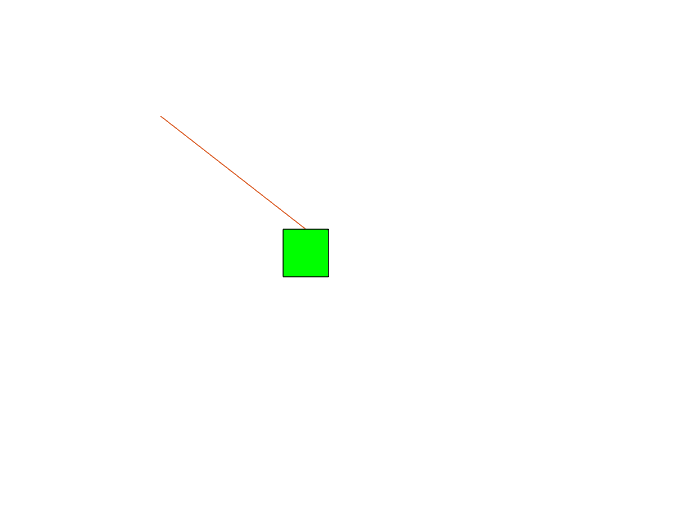

animate(xb,th,t,l)

Funzione per animare

function animation = animate(xb,th,t,l)
    n = length(xb)-1;
    for i = 1:n
        clf
        x = xb(i);
        h=plot([-l/8 -l/8 l/8 l/8]+x,[0 l/4 l/4 0],[0+x x-l*sin(th(i))],[l/4 l/4+l*cos(th(i))]);
        set(gca, 'Visible', 0)
        hold on
        patch([-l/8 -l/8 l/8 l/8]+x,[0 l/4 l/4 0], 'g')
        ylim([-l l+l/4]);
        xlim([-l 2*l]);
        set(gca,'color',[0 0 0])
        pause(t(i+1)-t(i))
    end
end